# Plot Feedback Linearization

Objective: This script tests the *feedbackLin* function. It outputs a live animation of a robot moving toward a goal using the velocity commands calculated via the *feedbackLin* function. 

Helper Functions in this exercise:

- *plotFeedbackLin *creates a live animation of the robot moving toward the specified goal (green circle). The resulting trajectory is show as the blue line. 

Exercise:

Here are the variables are necessary inputs to solve for feedback linearization. They describe the current state of the robot, the intended waypoint, and the parameters that affect the path created by using the feedback linearization technique. 

%Define inputs
goal_xy = [5;5]; %Goal position
pose_current = [0;0; pi/2]; %Current position of robot
maxWheelSpeed = 10;
K = 1;
epsilon = 0.14;
Vxy_global = K*(goal_xy - pose_current(1:2)); 

Use *feedbackLin *and *limitCommands* below to calculate $V$ and $\omega$ to command the robot. 

**COMPLETE THE CODE BELOW**

[V, omega] = feedbackLin(Vxy_global(1),Vxy_global(2),pose_current(3),epsilon); %Insert your code here
[V, omega] = limitCommands(V,omega,maxWheelSpeed); %Insert your code here

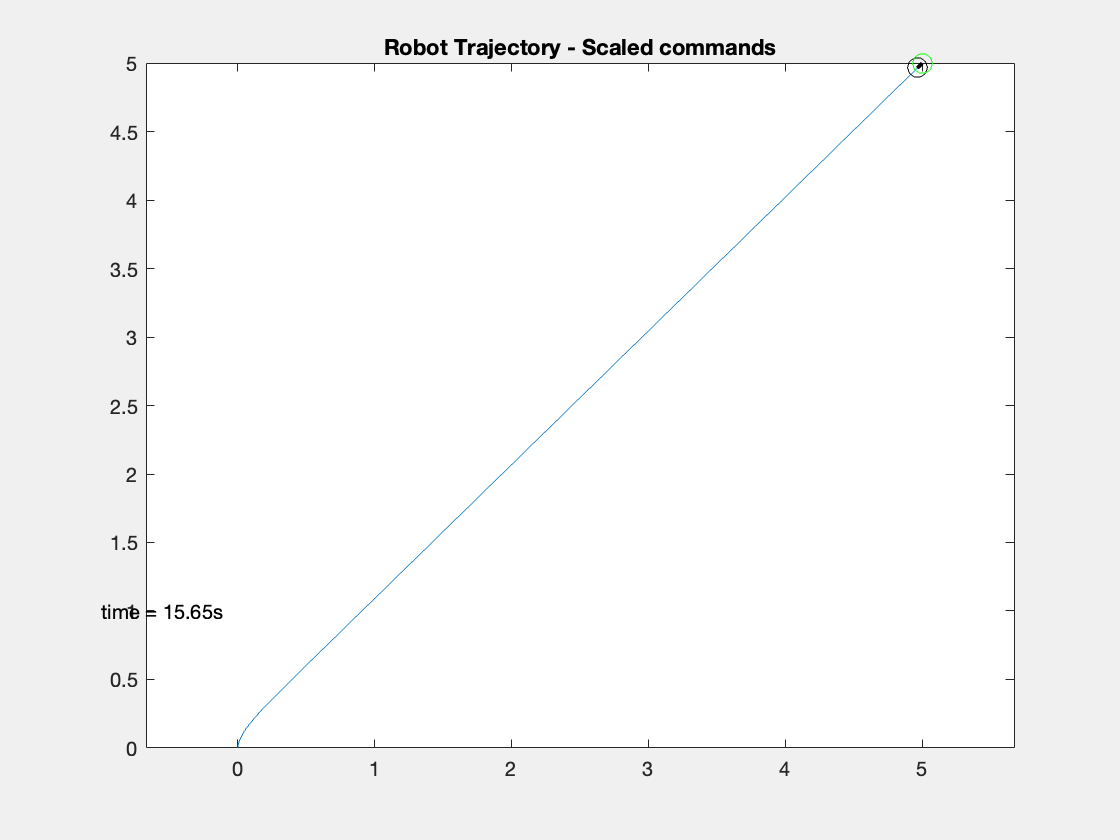

%Plot
plotFeedbackLin(goal_xy,pose_current,epsilon,maxWheelSpeed,K, "Robot Trajectory")

Expected Results: If you're feedbackLin function is correct, running this section of the script will create an animation of the robot using feedback linearization to drive from an initial point to a goal pose. 

Check your Comprehension: Use this code to test your function and play around with the parameters to get a better intuition of the feedback linearization techniques. There are many different factors that affect the curvature and shape of the robot trajectory:

- Vary the goal position of the robot in relation to where the robot is initially facing. How do the trajectories differ?

- Try different values for K and epsilon given the same goal position. How do the trajectories differ?